# IRS-assisted 802.11ad link

This code integrates an IRS module within an 802.11ad link. As described in Fig. 1, the link comprises an access point (AP) with a non-line-of-sight (NLoS) connection to the mobile user (MU). The connection is made by the line-of-sight (LoS) connection between the AP and IRS and between the IRS and the MU.

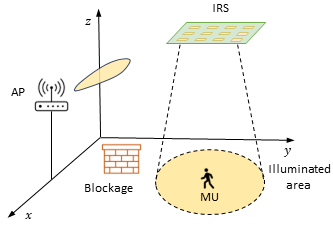

Fig 1: IRS-assisted link between an access point (AP) and a mobile user (MU).

The code is divided into three modules: the IRS settings, the evaluation of the SNR in the ground plane, and the evaluation of the age of information (AoI). Results are illustrated as plots in the results folder. The files used to implement these blocks are the following

- `Parameters` file: This file evaluates all the parameters for the system model, including the position of the communication components, communication frame slots following the 802.11as standard, power, and noise levels, and the user's mobility.

- `IRS_config` file: This file computes the path loss and the SNR in the link AP-IRS-MU as observed by the MU.

- `IRS_802_11ad` file: This file implements the link AP-IRS-MU and evaluates the SNR at the packet error rate (PER) at the MU position within the 802.11ad std.

- `simulation_results`: This file stores the calculation of the path loss, SNR, PER, and throughput observed at the MU position in polar coordinates centered at the illuminated area. These results are evaluated using the IRS_802_11ad file and the Parameters file. The path loss, SNR, PER, and throughput are stored as arrays with the same name referring to               

- `pathloss` matrix: It is a 50x50 matrix that stores the pathloss values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `SNR` matrix: It is a 50x50 matrix that stores the SNR values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `PER` matrix: It is a 50x50 matrix that stores the PER values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `troughput` array: It is column vector that evaluates the throughput with the radius.

#### BLOCK I: Evaluating the SNR in ground plane

Description: This block evaluates the SNR observed at the ground plane with the center coordinates already specified in the `Parameters` file. The SNR is evaluated for the complete link AP-IRS-MU.

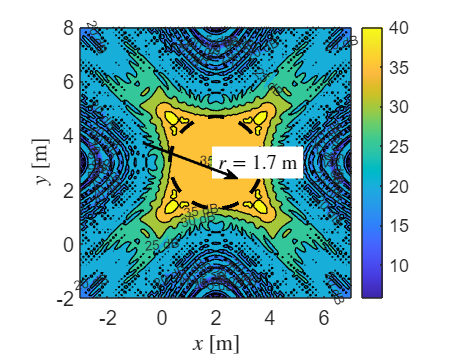

close all;

%running the scripts for the simulation parameters
Parameters
%evaluating the IRS coefficients
IRS_config

figure;
%conforming the grid in the xy-plane
y_points = p_center(2)+grid_point;
z_points = p_center(3)+grid_point;
[Y,Z]=meshgrid(y_points,z_points);

[M,c]=contourf(Y,Z,pow2db(SNR),"ShowText",true); hold on;
colorbar
c.LabelFormat="%0.0f dB";
c.LabelSpacing=1000;
c.FaceAlpha=1;

%plotting the circle or radius r
center=[2 3];
r = 1.7;% radius
q = 0:0.01:2*pi; % angle 0 to 360 degrees in radian
x = r*cos(q)+center(1);    % cartesian x coordinate
y = r*sin(q)+center(2);    % cartesian y coordinate
plot(x,y,'Color','black','LineStyle','--','LineWidth',3);

annotation("arrow",[0.3 0.5],[0.6 0.5],'Color','black','LineWidth',2);
text(2,3,strcat('$r=',num2str(r),'$ m'),'Interpreter','latex','FontSize',fontsize,'BackgroundColor','white');

axis square
xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);
%saving the plot to the results folder
saveas(gcf, './results/IRS.fig');
saveas(gcf, './results/IRS.svg');

#### **BLOCK II: Evaluating the SNR & Pathloss vs radius in the ground plane**

Description: This block  evaluate the PER observed at the MU position. The PER is evaluated with the radius from the center of the illuminated area. The plot is obtained 

Parameters
load simulation_results_MCS_12.mat
%(optionally) Uncomment the following line to re-evaluate the simulation
%results by runnig IRS_802_11ad code. This file performs quite heavy
%calculations. It took nearly a day to complete using an HPC computer of
%properties (CPU 4GHz and 200GB memory)
%IRS_802_11ad

%plotting SNR radius
figure;
total_simul=i_radius;
SNR_r_mean_dB=zeros(1,total_simul);%evaluates the expection of the SNR with the radius
SNR_r_std_dB=zeros(1,total_simul);%evaluates the standard deviation of the SNR with the radius
pathloss_r=zeros(1,total_pos_points);

for i_radius=1:total_simul
    SNR_r_mean_dB(i_radius)=mean(SNR_rad_ang_dB(i_radius,1:total_simul));
    SNR_r_std_dB(i_radius)=std(SNR_rad_ang_dB(i_radius,1:total_simul));
    pathloss_r(i_radius)=mean(pathloss_rad_ang(i_radius,1:total_simul));
end

%coordinates for the confidence interval
r_MU_conf=[r_MU(1:total_simul) r_MU(total_simul:-1:1)];
SNR_conf_dB=[SNR_r_mean_dB+SNR_r_std_dB/2 SNR_r_mean_dB(end:-1:1)-SNR_r_std_dB(end:-1:1)/2];

plot(r_MU(1:total_simul),(SNR_r_mean_dB),'LineWidth',2);grid on;hold on
%plotting the confidence bounds
p = fill(r_MU_conf,SNR_conf_dB,[0 0.4470 0.7410]); hold on
p.FaceAlpha=0.5;
p.EdgeColor = 'none'; 
xlabel('Radius [m]','Interpreter','latex');
ylabel('$\mathrm{SNR}$ [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 2 26 40]);

%plotting the PER vs radius
yyaxis right
PER=sum(packet_errors_rad_ang,2)/numPackets/total_pos_points;%calculating the PER per radius value
semilogy(r_MU(1:total_simul),(PER(1:total_simul)),'o-','LineWidth',2,'MarkerIndices',1:3:length(r_MU));grid on;
ylabel('BER','Interpreter','latex');

hold off;
legend({'SNR [dB]','SNR standard deviation [dB]','BER'},'Interpreter','latex');
saveas(gcf, './results/PER_802_11_ad.fig');

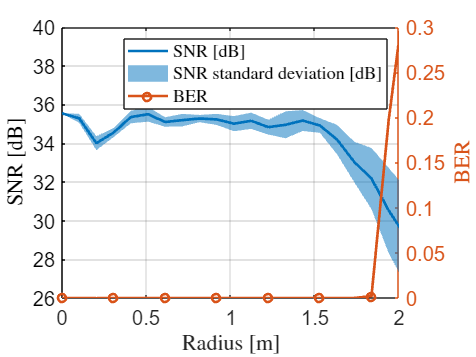

saveas(gcf, './results/PER_802_11_ad.svg');

#### **AoI calculation**

**Random Way Point (RWP) mobility model**

Evaluating $P_{\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

disp('Random Way Point mobility model')

Random Way Point mobility model


clear all
Parameters
P_r_in_code_RWP

**Evaluating **$P_\mathrm{out}(T_\mathrm{in}<T_\mathrm{upd})$

P_r_out_code_RWP

**Evaluating the average PAoI**

PAoI;
PAoI_RWP=P_AoI;

**Evaluating the minimum average PAoI with the radius**

PAoI_RWP_Min=zeros(1,length(r_inner));
tau=(0:tau_length-1)*delta_tau_j;
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP(r,:));
    PAoI_RWP_Min(r)=tau(idx);
end

**Calculating the Overhead**

r_select=5;
T_upd_opt=PAoI_RWP_Min(r_select);
c_h=ceil((T_upd_opt-(T_IRS+T_loc))/(T_p_ovh+T_data+idleTime));

%Overhead due to the packet preamble
ovh=(c_h*(T_p_ovh+idleTime))/T_upd_opt*100;
disp(['Overhead due to packet preamble->',num2str(ovh),'%']);

Overhead due to packet preamble->8.8159%



%Total Overhead
ovh=(T_loc+T_IRS+c_h*(T_p_ovh+idleTime))/T_upd_opt*100;
disp(['Total Overhead->',num2str(ovh),'%']);

Total Overhead->9.6113%


**Plotting conditional probabilities**

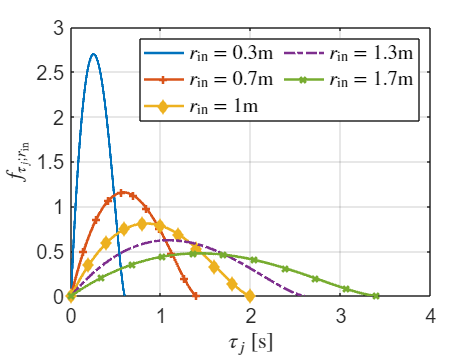

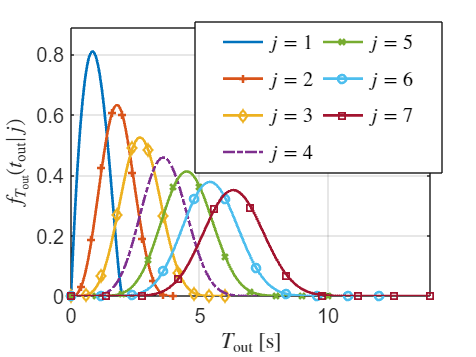

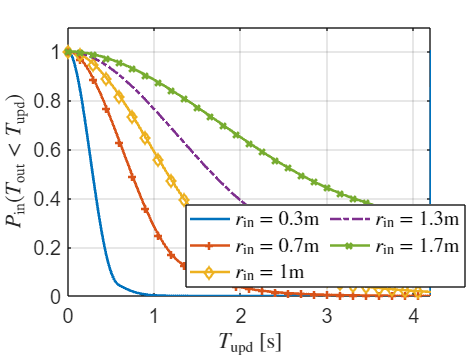

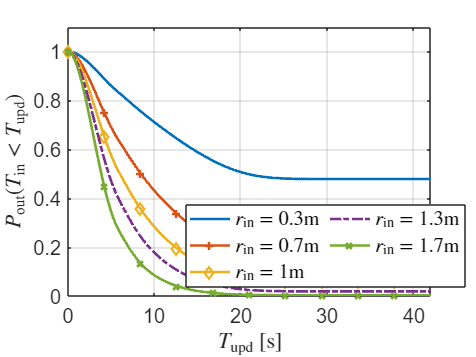

Plotting_probabilities

**Plotting the average PAoI**

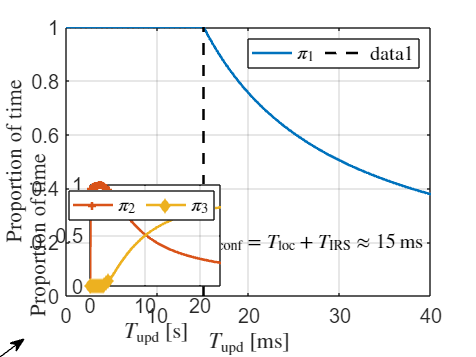

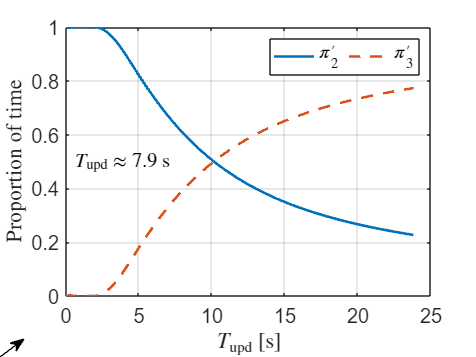

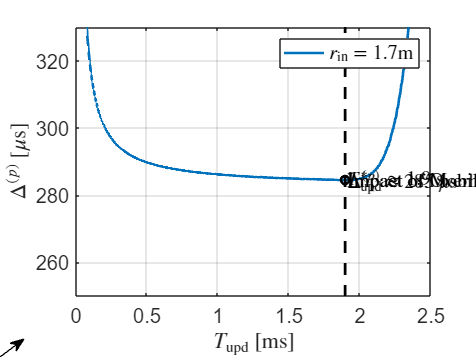

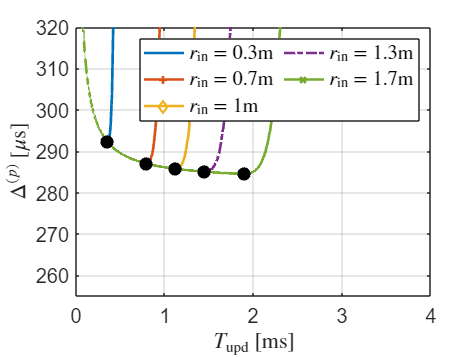

PAoI=PAoI_RWP;
Plotting_PAoI;


save PAoI_RWP_file PAoI_RWP PAoI_RWP_Min

### RWP with stop time

#### Evaluating $P_{r_\mathrm{out}}(T_\mathrm{in}<T_\mathrm{upd})$

clear all
Parameters
P_r_in_code_RWP_stop_time

#### Evaluating $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

P_r_out_code_RWP_stop_time

% Uncomment below for plotting the probabilities
% Plotting_probabilities

**Evaluating the average PAoI**

PAoI;
PAoI_RWP_StopTime=P_AoI;

**Stop time: Evaluating the minimum PAoI vs radius**

PAoI_RWP_StopTime_Min=zeros(1,length(r_inner));
tau=(0:tau_length-1)*delta_tau_j;
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP_StopTime(r,:));
    PAoI_RWP_StopTime_Min(r)=tau(idx);
end

%saving results for 2s stop time
save PAoI_RWP_StopTime_file_2s PAoI_RWP_StopTime PAoI_RWP_StopTime_Min

%saving results for 4s stop time
% PAoI_RWP_StopTime_Min_4s=PAoI_RWP_StopTime_Min;
% save PAoI_RWP_StopTime_file_4s PAoI_RWP_StopTime PAoI_RWP_StopTime_Min_4s

%saving results for 6s stop time
% PAoI_RWP_StopTime_Min_6s=PAoI_RWP_StopTime_Min;
% save PAoI_RWP_StopTime_file_6s PAoI_RWP_StopTime PAoI_RWP_StopTime_Min_6s


% Uncomment below for plotting the PAoI
% PAoI=PAoI_RWP_StopTime;
% Plotting_PAoI;

### RWP with random speed

#### Evaluating $P_{r_\mathrm{out}}(T_\mathrm{in}<T_\mathrm{upd})$

clear all
Parameters
P_r_in_code_RWP_random_speed

#### Evaluating $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

P_r_out_code_RWP_ramdon_speed

% Uncomment for plotting the probabilities
% Plotting_probabilities

**Evaluating the average PAoI**

PAoI;
PAoI_RWP_RandomVelocity=P_AoI;

**Stop time: Evaluating the minimum PAoI vs radius**

PAoI_RWP_RandomVelocity_Min=zeros(1,length(r_inner));
tau=(0:tau_length-1)*delta_tau_j;
for r=1:length(r_inner)
    [Min,idx]=min(PAoI_RWP_RandomVelocity(r,:));
    PAoI_RWP_RandomVelocity_Min(r)=tau(idx);
end

save PAoI_RWP_RandomVelocity_file PAoI_RWP_RandomVelocity PAoI_RWP_RandomVelocity_Min

% Uncomment below for plotting the PAoI
% PAoI=PAoI_RWP_RandomVelocity;
% Plotting_PAoI;

**Plotting T_upd vs r for the various mobility models**

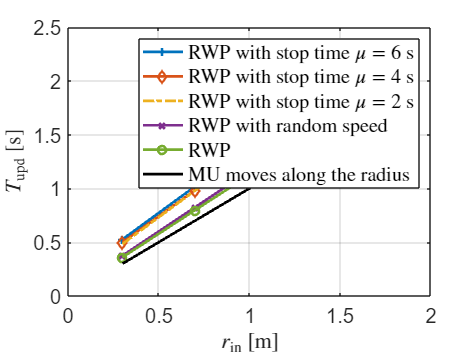

load PAoI_RWP_file
load PAoI_RWP_StopTime_file_2s
load PAoI_RWP_StopTime_file_4s
load PAoI_RWP_StopTime_file_6s
load PAoI_RWP_RandomVelocity_file.mat

figure;
plot(r_inner,PAoI_RWP_StopTime_Min_6s,marker{2},'LineWidth',2);hold on; grid on;
plot(r_inner,PAoI_RWP_StopTime_Min_4s,marker{3},'LineWidth',2);
plot(r_inner,PAoI_RWP_StopTime_Min,marker{4},'LineWidth',2);
plot(r_inner,PAoI_RWP_RandomVelocity_Min,marker{5},'LineWidth',2);
plot(r_inner,PAoI_RWP_Min,marker{6},'LineWidth',2);
plot(r_inner,r_inner/v,'LineWidth',2,'Color','black');

legend({'RWP with stop time $\mu=6$ s','RWP with stop time $\mu=4$ s','RWP with stop time $\mu=2$ s','RWP with random speed','RWP','MU moves along the radius'},...
    'Location','northeast','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

ylabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
xlabel('$r_\mathrm{in}$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize)
grid on;

saveas(gcf, './results/T_upd_vs_r.fig');
saveas(gcf, './results/T_upd_vs_r.svg');